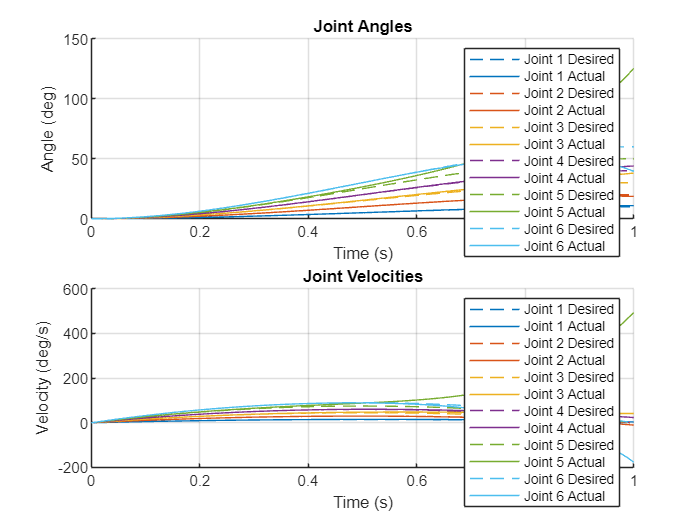

clear all; clc;

% Define manipulator parameters
n = 6; % Number of joints

g = [0; 0; -9810]; % Gravity vector (m/s^2)


R{1} = eye(3);
R{2} = [[1;0;0],[0;0;1],[0;1;0]];
R{3} = eye(3);
R{4} = [[-1;0;0],[0;0;-1],[0;-1;0]];
R{5} = [[0;1;0],[0;0;1],[1;0;0]];
R{6} = [[0;0;1],[0;-1;0],[1;0;0]];

p{1} = [-19.14;-24.76;-410.64];
p{2} = [-30.85;271.45;-195.43];
p{3} = [-0.01;296.72;155.18];
p{4} = [2;-15;-355.72];
p{5} = [212.52;-1.97;-0.14];
p{6} = [0.17;0;-70.38];

% Configuration matrices M_{i,i-1} (frames at centers of mass)
M{1} = [R{1},p{1};0 0 0 1]; % M_{1,0}
M{2} = [R{2},p{2};0 0 0 1]; % M_{2,1}
M{3} = [R{3},p{3};0 0 0 1]; % M_{3,2}
M{4} = [R{4},p{4};0 0 0 1]; % M_{4,3}
M{5} = [R{5},p{5};0 0 0 1]; % M_{5,4}
M{6} = [R{6},p{6};0 0 0 1]; % M_{6,5}
M{7} = [eye(3),[0;0;1];0 0 0 1]; % M_{6,5}

% Screw axes A_i (expressed in COM frames)
A{1} = [0; 0; 1; -24.76; 19.21; 0]; % Joint 1
A{2} = [0; 0; 1; 206.86; 0.20; 0]; % Joint 2
A{3} = [0; 0; 1; 3.57; 0.08; 0]; % Joint 3
A{4} = [0; 0; 1; 0.01; 1.7; 0]; % Joint 4
A{5} = [0; 0; 1; 0; 22.96; 0]; % Joint 5
A{6} = [0; 0; 1; 0; -0.24; 0]; % Joint 6

% Mass array (grams)
masses = {16934.57, 14350.90, 7501.51, 6420.43, 568.77, 30.98};

% Inertia tensor cell array (grams * mm^2)
inertias = {
    [222318392.93, 16499490.67, 23794307.09; ...
     16499490.67, 208958862.85, 31663043.13; ...
     23794307.09, 31663043.13, 157080928.32], ...
    [595207225.54, 7542.68, 4677.18; ...
     7542.68, 59862591.19, 3766250.53; ...
     4677.18, 3766250.53, 625682621.55], ...
    [58901544.85, -792.98, 60.73; ...
     -792.98, 34271484.89, 3671694.41; ...
     60.73, 3671694.41, 56883800.79], ...
    [103998943.85, 3156.05, -1379337.12; ...
     3156.05, 98782248.66, -7047.88; ...
     -1379337.12, -7047.88, 19071254.39], ...
    [382719.09, -11.58, 899.66; ...
     -11.58, 1083683.83, 1.21; ...
     899.66, 1.21, 1122865.92], ...
    [382719.09, -11.58, 899.66; ...
     -11.58, 1083683.83, 1.21; ...
     899.66, 1.21, 1122865.92]
};

G = compute_spatial_inertia(masses, inertias);



% Simulation parameters
tf = 1.0; % Simulation time (s)
N = 500; % Number of integration steps
dt = tf / N;
t = linspace(0, tf, N+1);

theta_start = [0; 0; 0; 0; 0; 0];
theta_end = [10*pi/180; 20*pi/180; 30*pi/180; 40*pi/180; 50*pi/180; 60*pi/180];


[theta_d, theta_dot_d, theta_ddot_d] = jointspace_traj(theta_start, theta_end, tf, N, 'cubic');


% Initial conditions
theta0 = theta_d(:,1);
theta_dot0 = theta_dot_d(:,1);


% Simulation storage
theta = zeros(n, N+1);
theta_dot = zeros(n, N+1);
theta(:,1) = theta0;
theta_dot(:,1) = theta_dot0;
F_tip = [0; 0; 0; 0; 0; 0]; % External wrench (N·m, N)

tau_array = zeros(n, N+1);

% Feedforward torque computation
for k = 1:N+1
    tau_array(:,k) = inverse_dynamics(theta_d(:,k), theta_dot_d(:,k), theta_ddot_d(:,k), F_tip, M, A, G, g);
end

% Forward simulation using precomputed torques
for k = 1:N
    tau = tau_array(:,k);
    
    f1 = compute_forward_dynamics(theta(:,k), theta_dot(:,k), tau, F_tip, M, A, G, g);
    f2 = compute_forward_dynamics(theta(:,k) + 0.5*dt*theta_dot(:,k), theta_dot(:,k) + 0.5*dt*f1, tau, F_tip, M, A, G, g);
    f3 = compute_forward_dynamics(theta(:,k) + 0.5*dt*theta_dot(:,k) + 0.25*dt^2*f1, theta_dot(:,k) + 0.5*dt*f2, tau, F_tip, M, A, G, g);
    f4 = compute_forward_dynamics(theta(:,k) + dt*theta_dot(:,k) + 0.5*dt^2*f2, theta_dot(:,k) + dt*f3, tau, F_tip, M, A, G, g);

    theta(:,k+1) = theta(:,k) + dt*theta_dot(:,k) + (dt^2/6)*(f1 + 2*f2 + 2*f3 + f4);
    theta_dot(:,k+1) = theta_dot(:,k) + (dt/6)*(f1 + 2*f2 + 2*f3 + f4);
end


% Plot all trajectories in degrees
figure;
% Plot joint angles
subplot(2,1,1);
hold on;
colors = lines(n);
for i = 1:n
    plot(t, rad2deg(theta_d(i,:)), 'Color', colors(i,:), 'LineStyle', '--', 'DisplayName', sprintf('Joint %d Desired', i));
    plot(t, rad2deg(theta(i,:)), 'Color', colors(i,:), 'LineStyle', '-', 'DisplayName', sprintf('Joint %d Actual', i));
end
title('Joint Angles');
xlabel('Time (s)');
ylabel('Angle (deg)');
legend('show');
grid on;
hold off;

% Plot joint velocities
subplot(2,1,2);
hold on;
for i = 1:n
    plot(t, rad2deg(theta_dot_d(i,:)), 'Color', colors(i,:), 'LineStyle', '--', 'DisplayName', sprintf('Joint %d Desired', i));
    plot(t, rad2deg(theta_dot(i,:)), 'Color', colors(i,:), 'LineStyle', '-', 'DisplayName', sprintf('Joint %d Actual', i));
end
title('Joint Velocities');
xlabel('Time (s)');
ylabel('Velocity (deg/s)');
legend('show');
grid on;
hold off;

function J = compute_jacobian(theta, M, A)
    n = length(theta);
    J_s = zeros(6, n); % Spatial Jacobian
    
    M_0_i = cell(n, 1);
    T = eye(4);
    for i = 1:n
        T = T * inv(M{i});
        M_0_i{i} = T;
    end
    
    S = cell(n, 1);
    for i = 1:n
        Ad_M_0_i = adjoint(M_0_i{i});
        S{i} = Ad_M_0_i * A{i};
    end
    
    T = eye(4);
    for i = 1:n
        Ad_T = adjoint(T);
        J_s(:,i) = Ad_T * S{i};
        T = T * expm(skew(S{i}) * theta(i));
    end
    
    Ad_T_inv = adjoint(inv(T));
    J = Ad_T_inv * J_s;
end

function tau = inverse_dynamics(theta, theta_dot, theta_ddot, F_tip, M, A, G, g)
    n = length(theta);
    nu = cell(n+1, 1);
    nu_dot = cell(n+1, 1);
    F = cell(n+1, 1);
    tau = zeros(n, 1);
    
    nu{1} = zeros(6,1);
    nu_dot{1} = [zeros(3,1); -g];
    F{n+1} = F_tip;
    
    for i = 1:n
        T_i_im1 = expm(skew(A{i}) * theta(i)) * M{i}; % Fixed convention
        Ad_T_i_im1 = adjoint(T_i_im1);
        nu{i+1} = A{i} * theta_dot(i) + Ad_T_i_im1 * nu{i};
        ad_nu_i = ad_matrix(nu{i+1});
        nu_dot{i+1} = A{i} * theta_ddot(i) + Ad_T_i_im1 * nu_dot{i} + ad_nu_i * A{i} * theta_dot(i);
    end
    
    for i = n:-1:1
        if i == n
            T_ip1_i = M{n+1};
        else
            T_ip1_i = expm(skew(A{i+1}) * theta(i+1)) * M{i+1}; % Fixed convention
        end
        Ad_T_ip1_i_T = adjoint(T_ip1_i)';
        ad_nu_i_T = ad_matrix(nu{i+1})';
        F{i} = Ad_T_ip1_i_T * F{i+1} + G{i} * nu_dot{i+1} - ad_nu_i_T * (G{i} * nu{i+1});
        tau(i) = F{i}' * A{i};
    end
end

function [theta, theta_dot] = forward_dynamics(theta0, theta_dot0, tau, F_tip, M, A, G, g, tf, N)
    n = length(theta0);
    dt = tf / N;
    theta = zeros(n, N+1);
    theta_dot = zeros(n, N+1);
    theta(:,1) = theta0;
    theta_dot(:,1) = theta_dot0;
    
    for k = 1:N
        t = (k-1) * dt;
        if isa(tau, 'function_handle')
            tau_k = tau(t);
        else
            tau_k = tau;
        end
        if isa(F_tip, 'function_handle')
            F_tip_k = F_tip(t);
        else
            F_tip_k = F_tip;
        end
        theta_ddot = compute_forward_dynamics(theta(:,k), theta_dot(:,k), tau_k, F_tip_k, M, A, G, g);
        theta(:,k+1) = theta(:,k) + theta_dot(:,k) * dt;
        theta_dot(:,k+1) = theta_dot(:,k) + theta_ddot * dt;
    end
end

function theta_ddot = compute_forward_dynamics(theta, theta_dot, tau, F_tip, M, A, G, g)
    n = length(theta);
    h = inverse_dynamics(theta, theta_dot, zeros(n,1), zeros(6,1), M, A, G, g);
    M_theta = zeros(n, n);
    for i = 1:n
        theta_ddot_i = zeros(n,1);
        theta_ddot_i(i) = 1;
        M_theta(:,i) = inverse_dynamics(theta, zeros(n,1), theta_ddot_i, zeros(6,1), M, A, G, zeros(3,1));
    end
    J = compute_jacobian(theta, M, A);
    theta_ddot = M_theta \ (tau - h - J' * F_tip);
end

function S = skew(v)
    if length(v) == 3
        S = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    elseif length(v) == 6
        omega = v(1:3);
        v_linear = v(4:6);
        omega_skew = [0, -omega(3), omega(2); omega(3), 0, -omega(1); -omega(2), omega(1), 0];
        S = [omega_skew, v_linear; zeros(1,3), 0];
    else
        error('Input vector must be 3x1 or 6x1');
    end
end

function Ad = adjoint(T)
    R = T(1:3, 1:3);
    p = T(1:3, 4);
    Ad = [R, zeros(3); skew(p) * R, R];
end

function ad = ad_matrix(V)
    omega = V(1:3);
    v = V(4:6);
    ad = [skew(omega), zeros(3); skew(v), skew(omega)];
end

function G = compute_spatial_inertia(masses, inertia_tensors)
    % COMPUTE_SPATIAL_INERTIA - Creates spatial inertia matrices from masses and inertia tensors
    % Inputs:
    %   masses - Cell array of scalar masses for each link (kg)
    %   inertia_tensors - Cell array of 3x3 inertia tensors for each link (kg·m^2)
    % Output:
    %   G - Cell array of 6x6 spatial inertia matrices
    
    n = length(masses); % Number of links
    G = cell(n, 1); % Initialize output cell array
    
    for i = 1:n
        % Extract mass and inertia tensor for the i-th link
        m = masses{i};
        I = inertia_tensors{i};
        
        % Construct 6x6 spatial inertia matrix
        % Format: [I, 0; 0, m*eye(3)]
        G{i} = [I, zeros(3); zeros(3), m * eye(3)];
    end
end

function [theta_d, theta_dot_d, theta_ddot_d] = jointspace_traj(theta_start, theta_end, tf, N, interp_type, kinematics_fn)
    % JOINTSPACE_TRAJ - Generate joint space trajectory for any robot manipulator
    % Inputs:
    %   theta_start - n x 1 vector of starting joint angles (rad)
    %   theta_end - n x 1 vector of ending joint angles (rad)
    %   tf - Total time of trajectory (s)
    %   N - Number of integration steps
    %   interp_type - String 'cubic' or 'quintic' for interpolation type
    %   kinematics_fn - Optional function handle for forward kinematics (default: identity)
    %                  Should take theta and return [x; y; z] if provided
    % Outputs:
    %   theta_d - n x (N+1) matrix of desired joint angles (rad)
    %   theta_dot_d - n x (N+1) matrix of desired joint velocities (rad/s)
    %   theta_ddot_d - n x (N+1) matrix of desired joint accelerations (rad/s^2)
    
    % Default to identity if no kinematics function provided
    if nargin < 6
        kinematics_fn = @(theta) theta; % Placeholder, assumes joint space input
    end
    
    % Number of joints
    n = length(theta_start);
    
    % Time vector
    t = linspace(0, tf, N+1);
    dt = tf / N;
    
    % Initialize output arrays
    theta_d = zeros(n, N+1);
    theta_dot_d = zeros(n, N+1);
    theta_ddot_d = zeros(n, N+1);
    
    % Compute spline coefficients for s(t)
    if strcmp(interp_type, 'cubic')
        % Cubic polynomial: s(t) = a0 + a1*t + a2*t^2 + a3*t^3
        % Boundary conditions: s(0)=0, s(tf)=1, ds/dt(0)=0, ds/dt(tf)=0
        A = [1, 0, 0, 0;
             1, tf, tf^2, tf^3;
             0, 1, 0, 0;
             0, 1, 2*tf, 3*tf^2];
        b = [0; 1; 0; 0];
        coeffs = A \ b; % Solve for [a0; a1; a2; a3]
        a0 = coeffs(1); a1 = coeffs(2); a2 = coeffs(3); a3 = coeffs(4);
        a4 = 0; a5 = 0; % Pad with zeros for consistency
    elseif strcmp(interp_type, 'quintic')
        % Quintic polynomial: s(t) = a0 + a1*t + a2*t^2 + a3*t^3 + a4*t^4 + a5*t^5
        % Boundary conditions: s(0)=0, s(tf)=1, ds/dt(0)=0, ds/dt(tf)=0, d2s/dt2(0)=0, d2s/dt2(tf)=0
        A = [1, 0, 0, 0, 0, 0;
             1, tf, tf^2, tf^3, tf^4, tf^5;
             0, 1, 0, 0, 0, 0;
             0, 1, 2*tf, 3*tf^2, 4*tf^3, 5*tf^4;
             0, 0, 2, 0, 0, 0;
             0, 0, 2, 6*tf, 12*tf^2, 20*tf^3];
        b = [0; 1; 0; 0; 0; 0];
        coeffs = A \ b; % Solve for [a0; a1; a2; a3; a4; a5]
        a0 = coeffs(1); a1 = coeffs(2); a2 = coeffs(3); a3 = coeffs(4); a4 = coeffs(5); a5 = coeffs(6);
    else
        error('interp_type must be ''cubic'' or ''quintic''');
    end
    
    % Compute s(t), ds/dt, and d2s/dt2
    for k = 1:N+1
        tau = t(k);
        s = a0 + a1*tau + a2*tau^2 + a3*tau^3 + a4*tau^4 + a5*tau^5;
        ds_dt = a1 + 2*a2*tau + 3*a3*tau^2 + 4*a4*tau^3 + 5*a5*tau^4;
        d2s_dt2 = 2*a2 + 6*a3*tau + 12*a4*tau^2 + 20*a5*tau^3;
        
        % Compute joint trajectory
        theta_d(:,k) = theta_start + s * (theta_end - theta_start);
        theta_dot_d(:,k) = ds_dt * (theta_end - theta_start);
        theta_ddot_d(:,k) = d2s_dt2 * (theta_end - theta_start);
    end
end



